# A5 Explicit MPC and Mimimum Time Control

## 1.Linear MPC design

consider the following system

The input and state constraints are

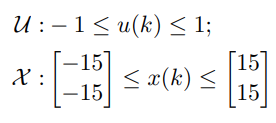

clc
clear
A = [1.2 1; 0 1];
B = [0;1];

model = LTISystem('A', A, 'B', B);     % unstable A
model.x.min = [-15; -15];
model.x.max = [ 15;  15];
model.u.min = -1;
model.u.max =  1;

X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

(a) Consider $Q=I_2,R=100,N=4,X_f=\mathbf{0}$

find a terminal $P_f$for the constrained RHC to guarantee asymptotic stability for all $x_0 \in X_N$

Q = eye(2);
R = 100;
N = 4;
Xf = Polyhedron([0 0]);
C_inf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


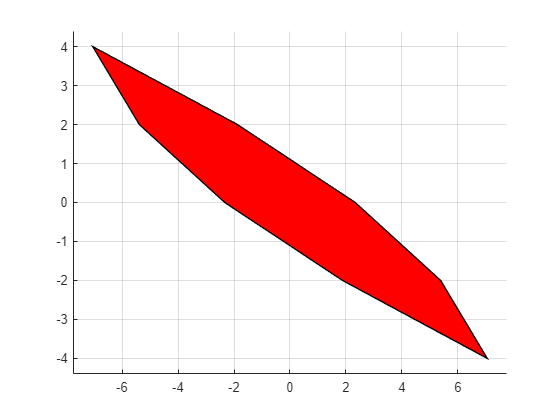


model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);
% terminal weight?
% P = dare(A,B,Q,R)
P      = model.LQRPenalty; % i.e. P is the DARE solution for this LQR
P.weight;
model.x.with('terminalPenalty');
model.x.terminalPenalty = QuadFunction(P.weight);


% terminal set 
Tset   = Xf;
model.x.with('terminalSet');
model.x.terminalSet = Tset;

% feasible set
XN = Tset;
for i=1:N
    back_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = back_XN.intersect(X).minHRep();
end
figure
plot(XN)

(b) Set x(0)=[7,-4]T, design a MPC for N = 10, 15, 20.

state prediction at time zero

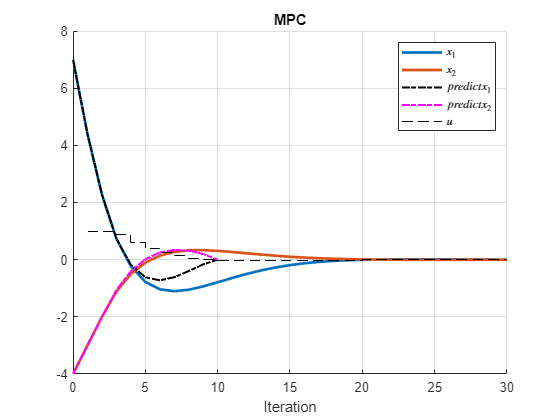

x0 = [7;-4];
Nsim = 30;
% N = 10;
N = 10;
mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
[u, feasible, openloop] = mpc.evaluate(x0);
pre_data = openloop;
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;grid on
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
plot(0:N, pre_data.X(1,:), '-.', 'Linewidth',1.5, 'Color','black')
plot(0:N, pre_data.X(2,:), '-.', 'Linewidth',1.5, 'Color','magenta')
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$predict x_1$', '$predict x_2$', '$u$'}, 'interpreter', 'latex')

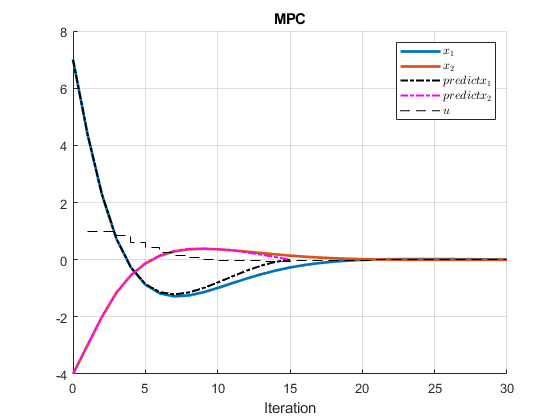


% N = 10;
N = 15;
mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
[u, feasible, openloop] = mpc.evaluate(x0);
pre_data = openloop;
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;grid on
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
plot(0:N, pre_data.X(1,:), '-.', 'Linewidth',1.5, 'Color','black')
plot(0:N, pre_data.X(2,:), '-.', 'Linewidth',1.5, 'Color','magenta')
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$predict x_1$', '$predict x_2$', '$u$'}, 'interpreter', 'latex')

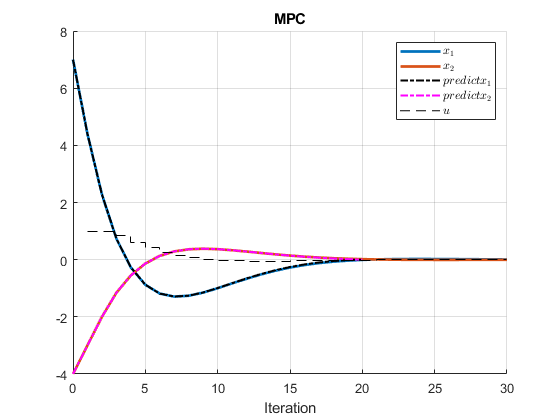


% N = 10;
N = 20;
mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
[u, feasible, openloop] = mpc.evaluate(x0);
pre_data = openloop;
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;grid on
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
plot(0:N, pre_data.X(1,:), '-.', 'Linewidth',1.5, 'Color','black')
plot(0:N, pre_data.X(2,:), '-.', 'Linewidth',1.5, 'Color','magenta')
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$predict x_1$', '$predict x_2$', '$u$'}, 'interpreter', 'latex')

(c) Assume N =20

Pf is riccati solutoin. Find explicit MPC solution and plot state-space partition

N = 20;

Xf = Polyhedron('lb', [-0.01;-0.01], 'ub', [0.01;0.01]);
model.x.terminalSet = Xf;

mpc = MPCController(model, N);
empc = mpc.toExplicit();

mpt_plcp: 71 regions


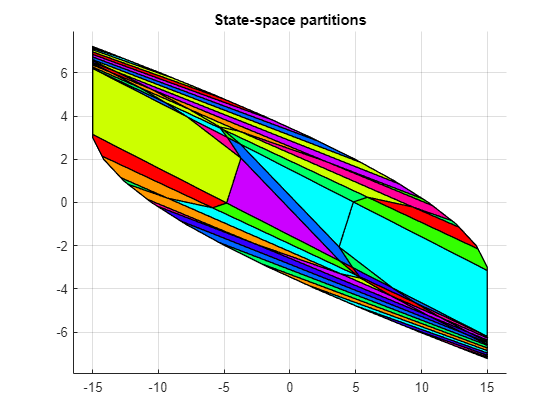


figure
empc.partition.plot();
title("State-space partitions")

(d)  Assume N = 1. Can you choose a new Xf so that persistent feasibility is guaranteed for all x0 belonging to C∞? Motivate your answer in the report.

disp("Problem (d)")

Problem (d)


N = 1;
C_inf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


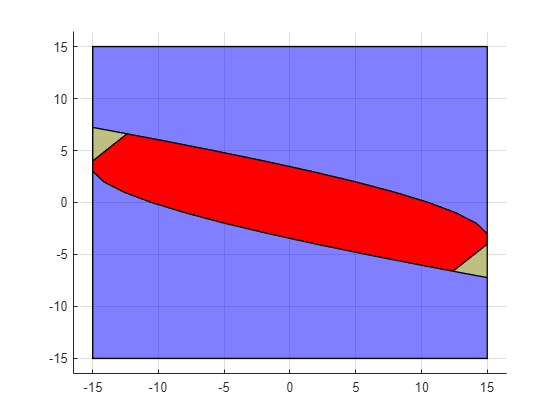

Xf_tmp = model.reachableSet('X', C_inf, 'U', U, 'direction', 'forward','N',1);
Xf = Xf_tmp.intersect(C_inf).minHRep();

figure
plot(X, 'alpha',0.5, 'color', 'blue')
hold on
plot(C_inf,'alpha', 0.5, 'color','yellow')
plot(Xf, 'color','red')

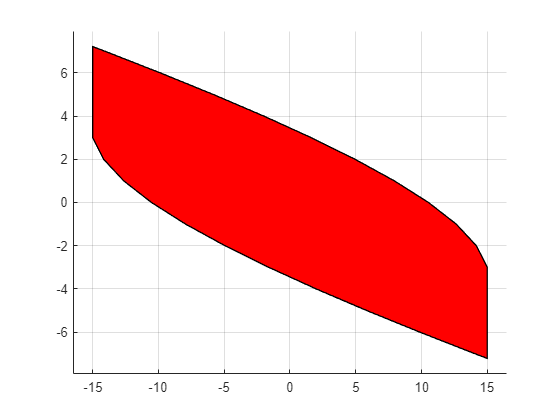


X0_tmp = model.reachableSet('X', Xf, 'U', U, 'direction', 'backward','N',1);
X0_tmp= X0_tmp.intersect(X).minHRep();
figure
plot(X0_tmp)

## 2.Finite time control of a DC motor

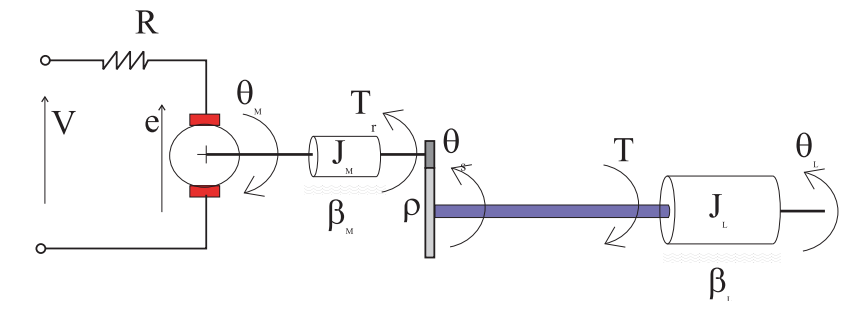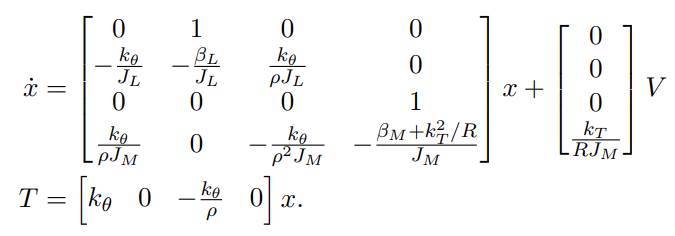

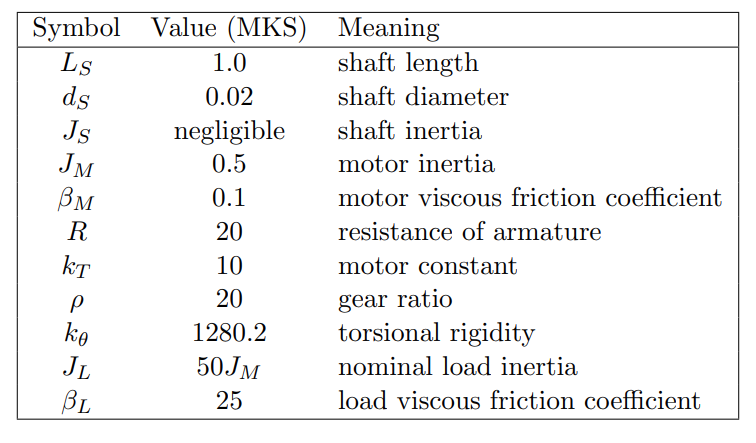

clc
clear
% parameters
LS = 1;
dS = 0.02;
JM = 0.5;
betaM = 0.1;
R = 20;
kT = 10;
rho = 20;
kth = 1280.2;
JL = 50*JM;
betaL = 25;

% state space equations
A = [0 1 0 0;
     -kth/JL -betaL/JL kth/(rho*JL) 0;
     0 0 0 1;
     kth/(rho*JM) 0 -kth/(rho^2*JM) -(betaM+kT^2/R)/JM];
B = [0 0 0 kT/(R*JM)]';
C = [kth 0 -kth/rho 0];
D = 0;

(a) create state space equations

dt = 0.1;
x0 = [0;2.5;0;75];
% [F,G] = c2d(A,B,dt)
% A = F;
% B = G;

sys=ss(A,B,C,D);
sys_d = c2d(sys,dt);
A = sys_d.A;
B = sys_d.B;
% size of the states and inputs
nx = size(A,2);
nu = size(B,2);

(b)

design a minimum-time controller to bring the states to 

% create system model
model = LTISystem('A', A, 'B', B, 'C', C);     % unstable A

% state constraints(temporarily none)

% input constraints
model.u.min = -200;
model.u.max = 200;
U = Polyhedron('lb',model.u.min,'ub',model.u.max);

% terminal constraints
% p1 = 0.023;
% p2 = inf;
% xsdp = sdpvar(nx, 1);
% state 2&4 should be around 0, state 1&3 has no constraints
% Xf = Polyhedron( [-p1<=xsdp([2,4])<=p1;-p2<=xsdp([1,3])<=p2] );
Xf = Polyhedron('Ae', [0 1 0 0; 0 0 0 1], 'be', [0;0]);
model.x.with('terminalSet');
model.x.terminalSet = Xf;

% C_inf = model.invariantSet();

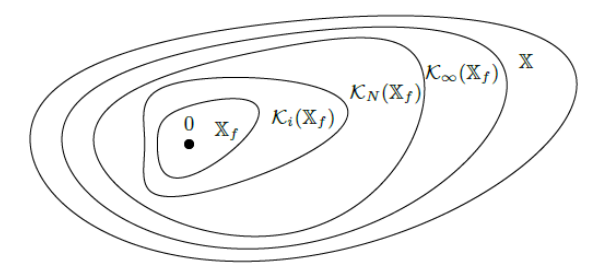

K(1) = Xf;

K(2) = K1(Xf);

% bring the state into Xf
% K(Xf)=pre(K(Xf)) and X, K0(Xf)=Xf
% 判断 x0 是否在 K_N(Xf)中
XN = Xf;
N = 0;
K = Xf;
for i = 1:100
    N = N+1
    %%%%%% Fill this part %%%%%%%%%%%
    %  It should return the feasible 
    %  set XN.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    K(i+1) = XN;
%     model.x.terminalSet = XN;
%     mpc = MPCController(model, 1);
%     u = mpc.evaluate(x0);
% 
%     x1 = A*x0 + B*u;
    if(XN.contains(x0))
        N
        break;
    end
%     XN.minHRep();
%     XN = back_XN.intersect(X).minHRep();
end

N = 1

N = 2

N = 3

N = 3

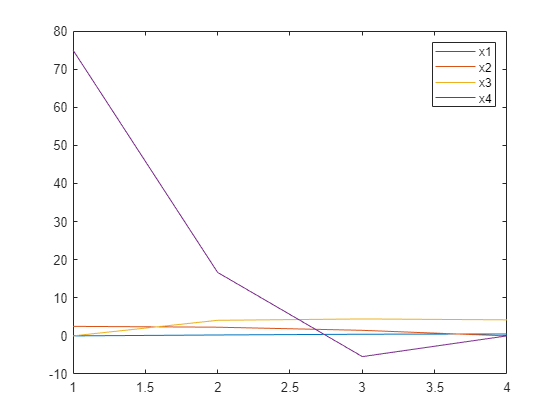

% 从x0出发
X0 = Polyhedron('Ae', [0 1 0 0; 0 0 0 1], 'be', [2.5;75]);
X1 = model.reachableSet('X', X0, 'U', U, 'direction', 'forward','N',1);
X1 = K(3);
model.x.terminalSet = X1;
mpc = MPCController(model, 1);
u0 = mpc.evaluate(x0);
x1 = A*x0 + B*u0;

% loop = ClosedLoop(mpc, model);
% data = loop.simulate(x0, 1);
% x1 = data.X(:,2);



X2 = model.reachableSet('X', X1, 'U', U, 'direction', 'forward','N',1);
X2 = K(2);
model.x.terminalSet = X2;
mpc = MPCController(model, 1);
u1 = mpc.evaluate(x1);
x2 = A*x1 + B*u1;

% loop = ClosedLoop(mpc, model);
% data = loop.simulate(x1, 1);
% x2 = data.X(:,2);

X3 = model.reachableSet('X', X2, 'U', U, 'direction', 'forward','N',1);
X1 = K(1);
model.x.terminalSet = X3;
mpc = MPCController(model, 1);
u2 = mpc.evaluate(x2);
x3 = A*x2 + B*u2;

% loop = ClosedLoop(mpc, model);
% data = loop.simulate(x2, 1);
% x3 = data.X(:,2);

states = [x0 x1 x2 x3];
% C = [kth 0 -kth/rho 0];
outputs = C*states;

figure
plot(states(1,:));
hold on
plot(states(2,:));
plot(states(3,:));
plot(states(4,:));
legend('x1', 'x2', 'x3', 'x4')

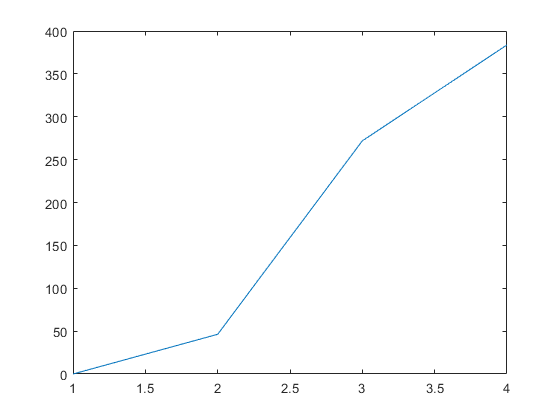

figure
plot(outputs(1,:));

% in loop
x0 = [0;2.5;0;75];
pre_states = x0;
xs = x0;
for i=1:N
    X1 = K(N-i+1);
    model.x.terminalSet = X1;
    mpc = MPCController(model, 1);
    u0 = mpc.evaluate(xs);
    xs = A*xs + B*u0;
    pre_states(:,end+1) = xs;
end

C = [kth 0 -kth/rho 0];
outputs = C*pre_states;

figure
plot(pre_states(1,:));
hold on
plot(pre_states(2,:));
plot(pre_states(3,:));
plot(pre_states(4,:));
legend('x1', 'x2', 'x3', 'x4')

figure
plot(outputs(1,:));

(c) With the same initial state as in b), design a minimum-time controller to bring the rotating shafts to standstill, such that the torsional torque is constrained within the range

   

Provide the minimum time and plot the predicted system states and output.

model = LTISystem('A', A, 'B', B,'C',C);
Xf = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
model.u.min = -200;
model.u.max = 200;
U=Polyhedron('lb',model.u.min,'ub',model.u.max);
model.x.with('terminalSet');
model.x.terminalSet = Xf;
X=Polyhedron('A',[C;-C],'b',[150;150]); 
model.x.with('setConstraint');
model.x.setConstraint=X;

x0=[0 2.5 0 75]';
K=Xf;

XN = Xf;
N = 0;
for i = 1:100
    N = N+1;
    XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = XN.intersect(X);
    K(i+1) = XN;
    if(XN.contains(x0))
        N
        break;
    end
end

N = 6


% N=0
% Tset = Polyhedron('Ae',[0 1 0 0; 0 0 0 1],'be',[0; 0]);
% while ~Tset.contains(x0)
% N=N+1;
% x_pre=model.reachableSet('X',Tset,'U',U,'N',1,'direction','backward');
% Tset=x_pre.intersect(X);
% K(N+1)=Tset;
% end

% 从x0出发
X1 = K(6);
model.x.with('terminalSet');

model.x.terminalSet = X1;
mpc = MPCController(model, 1);
u0 = mpc.evaluate(x0);
x1 = A*x0 + B*u0

x1 =     0.2431
    2.3739
    5.1539
   34.7825



X2 = K(5);
model.x.terminalSet = X2;
mpc = MPCController(model, 1);
u1 = mpc.evaluate(x1);
x2 = A*x1 + B*u1

x2 =     0.4665
    2.0320
    8.0716
   25.3186


% 
% % loop = ClosedLoop(mpc, model);
% % data = loop.simulate(x1, 1);
% % x2 = data.X(:,2);
% 
X3 = K(4);
model.x.terminalSet = X3;
mpc = MPCController(model, 1);
u2 = mpc.evaluate(x2);
x3 = A*x2 + B*u2

x3 =     0.6387
    1.3764
   10.4310
   22.4608



% 
% % loop = ClosedLoop(mpc, model);
% % data = loop.simulate(x2, 1);
% % x3 = data.X(:,2);

X4 = K(3);
model.x.terminalSet = X4;
mpc = MPCController(model, 1);
u3 = mpc.evaluate(x3);
x4 = A*x3 + B*u3

x4 =     0.7397
    0.6555
   12.4805
   19.0883



X5 = K(2);
model.x.terminalSet = X5;
mpc = MPCController(model, 1);
u4 = mpc.evaluate(x4);
x5 = A*x4 + B*u4

x5 =     0.7773
    0.1586
   14.4549
   20.0981



X6 = K(1);
model.x.terminalSet = X6;
mpc = MPCController(model, 1);
u5 = mpc.evaluate(x5);
x6 = A*x5 + B*u5

x6 =     0.7836
         0
   15.2953
    0.0000


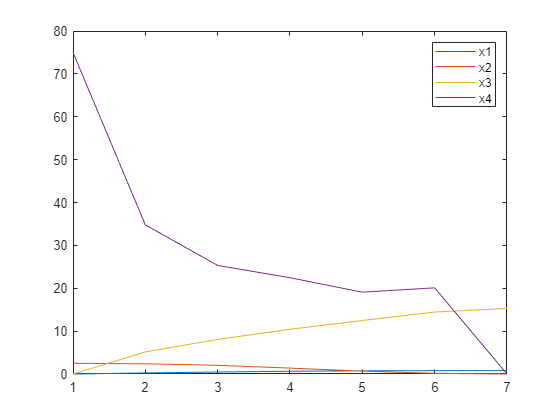


states = [x0 x1 x2 x3 x4 x5 x6];
% C = [kth 0 -kth/rho 0];
outputs = C*states;

figure
plot(states(1,:));
hold on
plot(states(2,:));
plot(states(3,:));
plot(states(4,:));
legend('x1', 'x2', 'x3', 'x4')

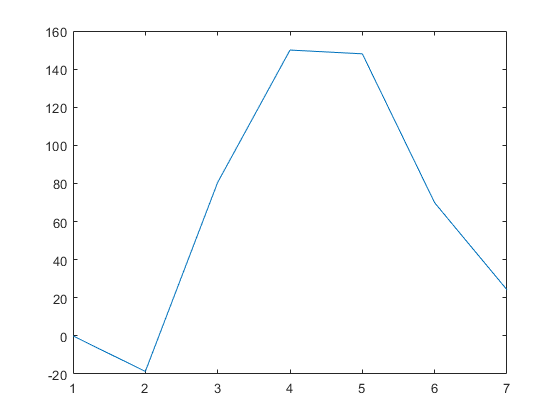

figure
plot(outputs(1,:));

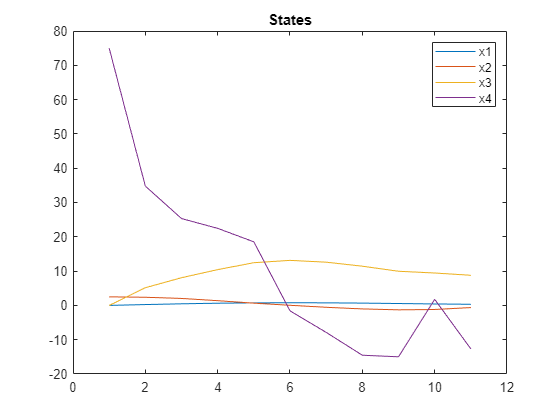

pre_states = x0;
xs = x0;
for i=1:N
    X1 = K(N-i+1);
    model.x.terminalSet = X1;
    mpc = MPCController(model, 1);
    u0 = mpc.evaluate(xs);
    xs = A*xs + B*u0;
%     xs
    pre_states(:,end+1) = xs;
end

C = [kth 0 -kth/rho 0];
outputs = C*pre_states;

figure
plot(pre_states(1,:));
hold on
plot(pre_states(2,:));
plot(pre_states(3,:));
plot(pre_states(4,:));
legend('x1', 'x2', 'x3', 'x4')
title("(c) States")

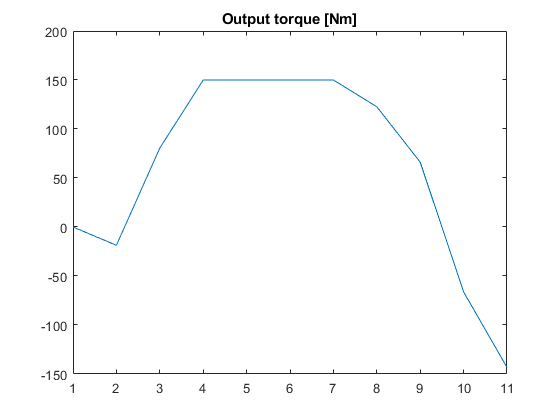

figure
plot(outputs(1,:));
title("Output torque [Nm]")

(d) With same initial condition

xsdp = sdpvar(nx, 1);
Ap = [eye(4); -eye(4)];
bp = [10;0.01;10;0.01;10;0.01;10;0.01];
% Xf = Polyhedron( [-0.01<=xsdp([2,4])<=0.01;-10<=xsdp([1,3])<=10] );
Xf = Polyhedron('A',Ap, 'b', bp);
model.x.terminalSet = Xf;
C_inf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...


Xf = C_inf.intersect(Xf).minHRep();
K(1) = Xf;

XN = Xf;
N = 0;
for i = 1:12
    N = N+1
    XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = XN.intersect(X);
    K(i+1) = XN;
    if(XN.contains(x0))
        N
        break;
    end
    if(i == 12)
        disp("out of 11")
    end
end

N = 1

N = 2

N = 3

N = 4

N = 5

N = 6

N = 7

N = 8

Predicted system states and outputs

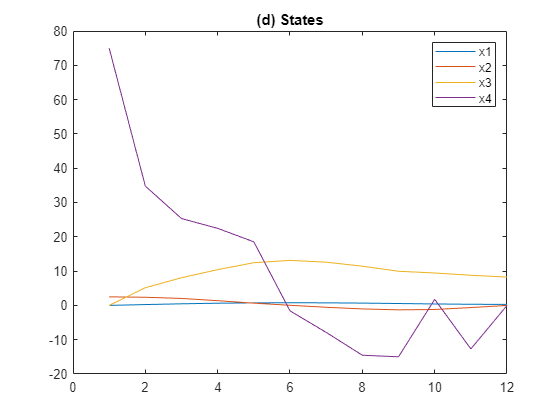

pre_states = x0;
xs = x0;
N = 11;
for i=1:N
    X1 = K(N-i+1);
    model.x.terminalSet = X1;
    mpc = MPCController(model, 1);
    u0 = mpc.evaluate(xs);
    xs = A*xs + B*u0;
%     xs
    pre_states(:,end+1) = xs;
end

C = [kth 0 -kth/rho 0];
outputs = C*pre_states;

figure
plot(pre_states(1,:));
hold on
plot(pre_states(2,:));
plot(pre_states(3,:));
plot(pre_states(4,:));
legend('x1', 'x2', 'x3', 'x4')
title("(d) States")

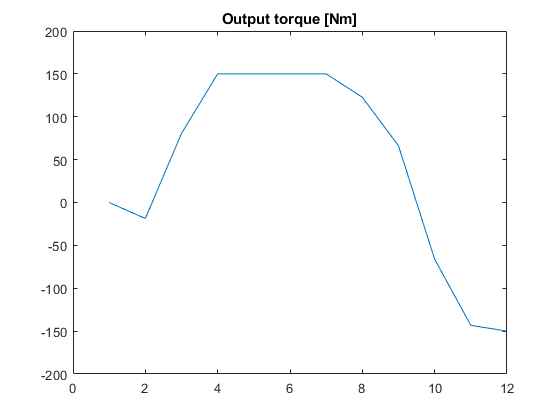

figure
plot(outputs(1,:));
title("Output torque [Nm]")

Xf = Polyhedron('A',Ap, 'b', bp);
% Xf = C_inf.intersect(Xf).minHRep();
X1 = Xf;
disp("1")

1


model.x.terminalSet = X1;
mpc = MPCController(model, N);
u0 = mpc.evaluate(x0)

u0 = 126.4517

loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, 1);
xs = data.X(:,2)

xs =     0.2431
    2.3739
    5.1539
   34.7825




disp("2")

2


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-1);
u0 = mpc.evaluate(xs)

u0 = 200.0000

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.4665
    2.0320
    8.0716
   25.3186



disp("3")

3


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-2);
u0 = mpc.evaluate(xs)

u0 = 200.0000

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.6387
    1.3764
   10.4310
   22.4608




disp("4")

4


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-3);
u0 = mpc.evaluate(xs)

u0 = 150.9473

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.7396
    0.6527
   12.4482
   18.5373



disp("5")

5


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-4);
u0 = mpc.evaluate(xs)

u0 = -146.7084

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.7735
    0.0348
   13.1268
   -1.5955



disp("6")

6


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-5);
u0 = mpc.evaluate(xs)

u0 = -131.6138

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.7472
   -0.5509
   12.6013
   -7.8668



disp("7")

7


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-6);
u0 = mpc.evaluate(xs)

u0 = -200.0000

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.6673
   -1.0225
   11.4284
  -14.5239



disp("8")

8


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-7);
u0 = mpc.evaluate(xs)

u0 = -164.7150

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.5494
   -1.2930
    9.9539
  -14.9843



disp("9")

9


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-8);
u0 = mpc.evaluate(xs)

u0 = 114.8191

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.4205
   -1.1952
    9.4445
    1.7714



disp("10")

10


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-9);
u0 = mpc.evaluate(xs)

u0 = -200.0000

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.3273
   -0.6280
    8.7843
  -12.6799



disp("11")

11


X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, N-10);
u0 = mpc.evaluate(xs)

u0 = 87.5051

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

xs =     0.2956
   -0.0100
    8.2563
   -0.0100



disp("12")

12


Xf = C_inf.intersect(Xf).minHRep();
X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, 1);
u0 = mpc.evaluate(xs)

u0 = NaN

loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);

xs = data.X(:,2)

Index in position 2 exceeds array bounds. Index must not exceed 1.


disp("13")
X1 = Xf;
model.x.terminalSet = X1;
mpc = MPCController(model, 1);
u0 = mpc.evaluate(xs)
loop = ClosedLoop(mpc, model);
data  = loop.simulate(xs, 1);
xs = data.X(:,2)

closed-loop controller. Simulate for 2s

Nsim = 20; % 2s, for sampling time 0.1s

pre_states = x0;
xs = x0;
for i = 1:Nsim
    if(i < 12)
        X1 = Xf; %K(N-i+1);
        model.x.terminalSet = X1;
        mpc  = MPCController(model, N-i+1);
        loop = ClosedLoop(mpc, model);
        data  = loop.simulate(xs, 1);
        xs = data.X(:,2);
        pre_states(:,end+1) = xs;
    else
        mpc  = MPCController(model, 1);
        loop = ClosedLoop(mpc, model);
        data  = loop.simulate(xs, 1);
        xs = data.X(:,2);
        pre_states(:,end+1) = xs;
    end
end

Index in position 2 exceeds array bounds. Index must not exceed 1.


C = [kth 0 -kth/rho 0];
outputs = C*pre_states;

figure
plot(pre_states(1,:));
hold on
plot(pre_states(2,:));
plot(pre_states(3,:));
plot(pre_states(4,:));
legend('x1', 'x2', 'x3', 'x4')
title("States")
figure
plot(outputs(1,:));
title("Output torque [Nm]")